# Position - Velocity Kalman Filter for an Airplane


clear; clc; close all; format bank;


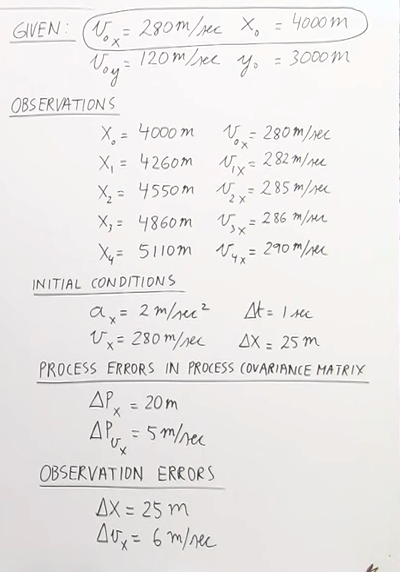

## States of the system - Position X, Velocity X

dt=1;
u= 2; 

## Defining System Plant


$$x= s + ut + \frac{1}{2}at^2$$



$$v= u+ at$$


system.A= [1 dt; 
           0 1];
system.B= [0.5*dt*dt; 
                 dt];
system.C= [1 0; 
           0 1];


## Defining covariances

#### Covariance of process noise- Q

#### Covariance of observation noise R

system.Q= [0 0; 0 0]; 

Ex= 25; % Measurement errors
Ev= 6;
% system.R= [Ex*Ex Ex*Ev; Ev*Ex Ev*Ev];
system.R= [Ex*Ex 0; 0 Ev*Ev];


## Defining Initial Conditions

EPx= 20; % Process errors in process co-variance matrix
EPv= 5;
% init_P= [EPx*EPx EPx*EPv; EPv*EPx EPv*EPv]
init_P= [EPx*EPx 0; 0 EPv*EPv]

init_P =         400.00             0
             0         25.00


init_x= [4000; 280];

## Measurements

z_pos= [4000, 4260, 4550, 4860, 5110];
z_vel= [280, 282, 285, 286, 290];
z= [z_pos; z_vel]

z =        4000.00       4260.00       4550.00       4860.00       5110.00
        280.00        282.00        285.00        286.00        290.00


## Loop One 

[apriori_x, apriori_Pk]= TimeUpdate(system, u, init_P, init_x)

apriori_x =        4281.00
        282.00


apriori_Pk =         425.00         25.00
         25.00         25.00


[predicted_state, error_covariance, KGain]= MeasurementUpdate(system, z(:,2), apriori_x, apriori_Pk)

predicted_state =        4272.62
        281.70


error_covariance =         249.31          8.87
          8.87         14.54


KGain =           0.40          0.25
          0.01          0.40


z_kf(:,1)= predicted_state;

## Loop Two

[apriori_x, apriori_Pk]= TimeUpdate(system, u, error_covariance, predicted_state)

apriori_x =        4555.33
        283.70


apriori_Pk =         281.59         23.41
         23.41         14.54


[predicted_state, error_covariance, KGain]= MeasurementUpdate(system, z(:,3), apriori_x, apriori_Pk)

predicted_state =        4554.14
        283.97


error_covariance =         188.91         11.64
         11.64         10.05


KGain =           0.30          0.32
          0.02          0.28


z_kf(:, 2)= predicted_state;

## Loop Three

[apriori_x, apriori_Pk]= TimeUpdate(system, u, error_covariance, predicted_state);
[predicted_state, error_covariance, KGain]= MeasurementUpdate(system, z(:,4), apriori_x, apriori_Pk);
z_kf(:,3)= predicted_state;

## Loop Four

[apriori_x, apriori_Pk]= TimeUpdate(system, u, error_covariance, predicted_state);
[predicted_state, error_covariance, KGain]= MeasurementUpdate(system, z(:,5), apriori_x, apriori_Pk);
z_kf(:, 4)= predicted_state;

# Graphs

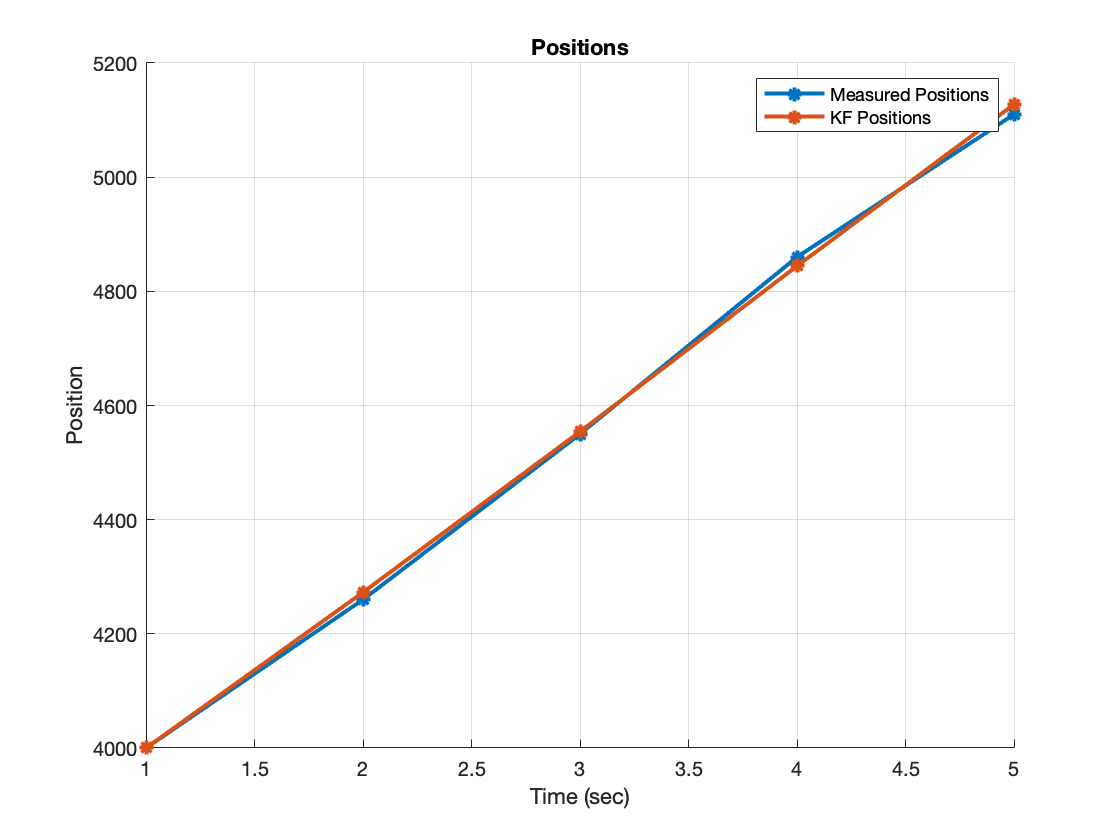

figure; hold on; grid on;
xlabel('Time (sec)');
ylabel({'Position'});
plot([1 2 3 4 5], z_pos, '*-', 'LineWidth',2);
plot([1 2 3 4 5], [z_pos(1), z_kf(1,:)], '*-', 'LineWidth',2);
legend('Measured Positions', 'KF Positions');
title('Positions');

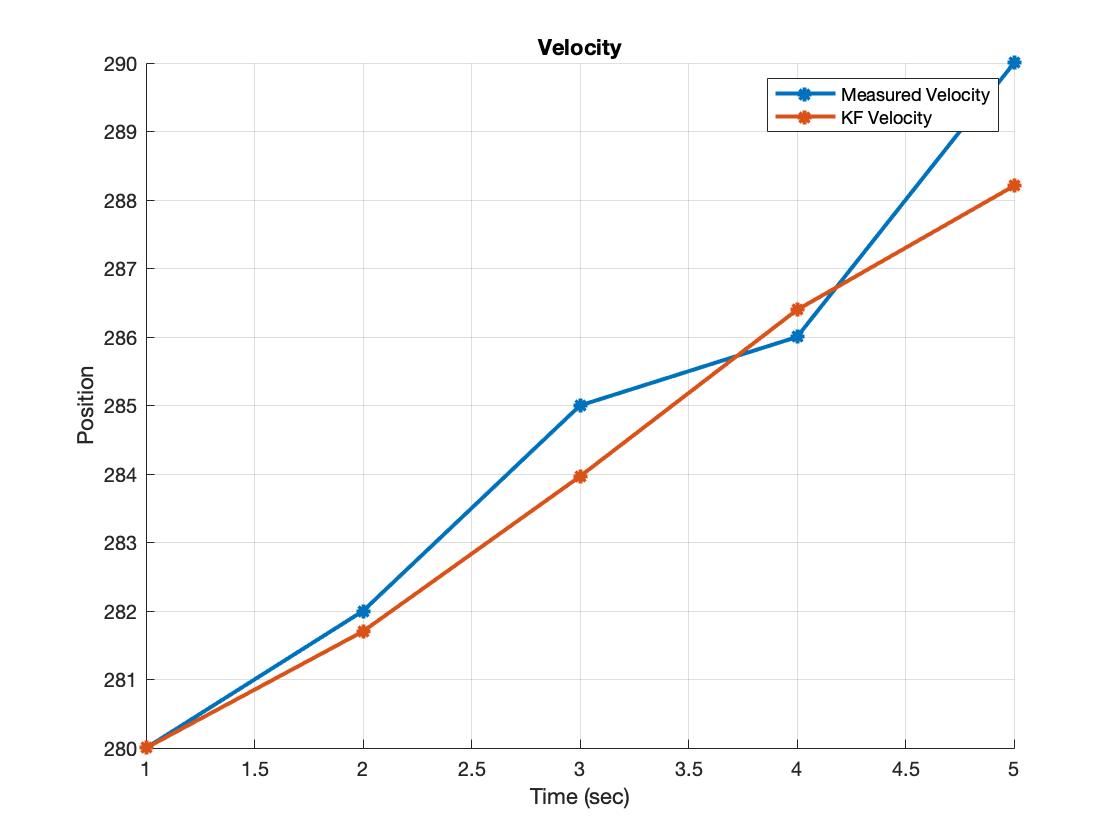

figure; hold on; grid on;
xlabel('Time (sec)');
ylabel({'Position'});
plot([1 2 3 4 5], z_vel, '*-', 'LineWidth',2);
plot([1 2 3 4 5], [z_vel(1), z_kf(2,:)], '*-', 'LineWidth',2);
legend('Measured Velocity', 'KF Velocity');
title('Velocity');

# Time Update part of Kalman Filter


$$\hat{x}^-_k = A\hat{x}^-_{k-1} + Bu_k$$



$$P_k^- = AP_{k-1}A^T + Q$$
 

function [apriori_x, apriori_Pk]= TimeUpdate(system, u, prev_P, prev_x)
    apriori_x= system.A*prev_x + system.B*u; 
    apriori_Pk= system.A*prev_P*system.A' + system.Q;
end

# Measurement Update part of Kalman Filter


$$K_k= P_k^-C^T(CP_k^-C^T + R)^{-1}$$



$$\hat{x}_k= \hat{x}_k + K_k(z - C\hat{x}_k^-)$$



$$P_k= (I - K_kH)P^-_k$$


function [predicted_state, error_covariance, K]= MeasurementUpdate(system, z, apriori_x, apriori_Pk)
    K= apriori_Pk*system.C'*inv(system.C*apriori_Pk*system.C' + system.R);
    predicted_state = apriori_x + K*(z - system.C*apriori_x);
    [r, ~]= size(K*system.C);
    error_covariance = (eye(r) - K*system.C)*apriori_Pk;
end